# Paper2 Fig6: local, global

## Setting up WS

CurrentFolder = pwd

CurrentFolder = '/home/lai-sang/Documents/GitHub/NYU-Vision-2Drive'

addpath(CurrentFolder)
addpath([CurrentFolder '/Utils'])
addpath([CurrentFolder '/Data'])
DataFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/Paper2PlotingData/']; % V1D2
DataFolder1 = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/GlobConv/']; % V1D2

addpath(DataFolder1)
addpath(DataFolder)
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/'])

FigurePaperPath = [CurrentFolder '/Paper2Figs/']; % V1D2

### B1. Load LDE computations and do Fr distributions

Should rerun Sect 1 after in case loaded file contain any paths.

DataPoint = 'V4D2'; %'V4D1'; 'V5D1'
load(sprintf("AllMFPixPara_Paper2TuneFig1%s.mat",DataPoint))

close all
SaveFolder = [CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/LocalConv/']; % V1D2

## 2. Set up LDE firing rate functions

first get basic function information

AngleList = {'0.0','7.5','15.0','22.5'};
DomList =  {'Small','Large'};


Choose from the list, but input can take everything between 0-180

AngleInpt = 0;% has to be multiples of 7.5
RotInd = floor(AngleInpt/45); % 0-3
MirInd = mod(floor(AngleInpt/22.5),2); % 0: no mirror; 1: mirror
switch MirInd % find the corresponding source
    case 0
        AngSource = mod(AngleInpt,45);
    case 1
        AngSource = mod(-AngleInpt,45);
end

% Use the source, decide which response function for angle should I use
AngFuncCtgrCdid = 0:7.5:22.5;
[~,AngFuncCtgr] = min(abs(AngFuncCtgrCdid - AngSource));

AngPrint = AngleList{AngFuncCtgr};
Angle = str2num(AngPrint); % can select from 0 7.5 15 22.5


load(sprintf('Func16%sAng%s%s.mat',DataPoint,AngPrint,DomList{1}),...
    'LDEFrfunc','L4EmeshX','L4ImeshY');

## Fig7a large ensumble for local

load('LDETraces_ang0.0.mat')
LDEequv = LDEEpoOut{end}; %Angle = 0;

N_HCOut = 4; PixNumOut = N_HCOut^2*NPixX*NPixY;
LGNlist = 4; L6list = 4;

Now note that LGN and L6 are not exactly corresponding to each other...L6 blurred

Grating = Angle; % degree
GratingHC = Grating + [0,45,90,135]; % grating for opt, obl1, ort, and obl2
LGNS_biphase = [45+abs(mod(GratingHC,180)-90)/2;
                45-abs(mod(GratingHC,180)-90)/2]*N_Slgn/1e3;

FigOn = false;
L6Ord_F_Grating = min(L6Ord_F) + ...
    (max(L6Ord_F)-min(L6Ord_F))*abs(mod(GratingHC,180)-90)/90;
L6S_Drive_Grating = L6Ord_F_Grating*NS_L6/1e3 * StimulusFac;
L6C_Drive_Grating = L6Ord_F_Grating*NC_L6/1e3 * StimulusFac; % only for investigation purpose

L6smear = n_S_HC*0.34; LGNsmear = n_S_HC*0.20;
TruncL6 = 1.25;TruncLGN = 1.0;
L6SFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
    N_HC,n_S_HC,L6smear,TruncL6,FigOn);
LGNFilt_Grating = SpatialGaussianFilt_my(OD_SMap,...
    N_HC,n_S_HC,LGNsmear,TruncLGN,FigOn);

PixL6Ctgr = LGNIndSpat(L6SFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);
PixLGNCtgr = LGNIndSpat(LGNFilt_Grating,1:4,NnSPixel,N_HC,N_HCOut,NPixX,NPixY);

However, the Ctgr for pixels needs to be rotated/flipped to represent the actual gratings

MirInd = logical(MirInd);
for Ctgr = 1:4
    PixL6Ctgr(:,Ctgr) = HCRot(PixL6Ctgr(:,Ctgr),RotInd,N_HCOut,NPixX,NPixY,MirInd);
    PixLGNCtgr(:,Ctgr) = HCRot(PixLGNCtgr(:,Ctgr),RotInd,N_HCOut,NPixX,NPixY,MirInd);
end

PixInptCtgrUse  = zeros(PixNumOut,LGNlist,L6list);
for PixInd = 1:PixNumOut
    PixInptCtgrUse(PixInd,:,:) = PixLGNCtgr(PixInd,:)' *PixL6Ctgr(PixInd,:);% by multiplying both indexes
end


Get pixelwise connectivities

C_SS_mean = AveSpatKer(C_SS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CS_mean = AveSpatKer(C_CS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IS_mean = AveSpatKer(C_IS_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SC_mean = AveSpatKer(C_SC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CC_mean = AveSpatKer(C_CC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_IC_mean = AveSpatKer(C_IC_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_SI_mean = AveSpatKer(C_SI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_CI_mean = AveSpatKer(C_CI_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);
C_II_mean = AveSpatKer(C_II_Pixel_Us,N_HC,N_HCOut,NPixX,NPixY);

start iteration

pAll = [0.2]; % 1-p for the original input
EpocTest = 31;

NSample = 500;
RadRange = 1:2:5;

  SaveName

SaveFName = 'FewStepsIter_NewSmwar_2Norm%d_p%.2f_Cub.mat';

  Neuron portions

PS = (1-CplxR)*0.8; PC = CplxR*0.8; PI = 0.2;

Creat novel equivalent condition

[PreTest,L2DiffNorm,L2DiffNormNeib,L2Diameter,~] = ...
            LDEIteration_16FuncMain(...
            PixInptCtgrUse,LDEequv,0.33,300,...
            C_SS_mean,C_CS_mean,C_IS_mean,...
            C_SC_mean,C_CC_mean,C_IC_mean,...
            C_SI_mean,C_CI_mean,C_II_mean,...
            L4EmeshX,L4ImeshY,LDEFrfunc,...
            N_HCOut,NPixX,NPixY,false,'xn')  ;

Run local tests

for p = pAll
    for RadInd = RadRange
        LDEequv = PreTest{end};
        Radius = 10^(-RadInd);
        SNoiseAll = normrnd(0,1,NPixY*NPixX,NSample)*Radius/PS;
        CNoiseAll = normrnd(0,1,NPixY*NPixX,NSample)*Radius/PC;
        INoiseAll = normrnd(0,1,NPixY*NPixX,NSample)*Radius/PI;

            Compute the norm of noises and normalize

        ENoiseAll = SNoiseAll*(1-CplxR) + CNoiseAll*CplxR;
        NoiNorm = sqrt(sum(ENoiseAll.^2 * 0.8^2 + INoiseAll.^2 * 0.2^2)/(NPixY*NPixX));
        NoiseAll = [SNoiseAll;CNoiseAll;INoiseAll];
        NoiseAll = NoiseAll./repmat(NoiNorm,NPixY*NPixX*3,1)*Radius;
        %OutBound = (NoiNorm>1e-7) | (NoiNorm<1e-10);
        %NoiseAll(:,OutBound) = [];
        %NoiseAll = diag(ones(NPixY*NPixX*3,1)) * Radius;
        
        LDEPertOutAll = cell(NSample,1);
        EpocTest = 31; %p = 0.2;
        L2Diff_OneStepAll = zeros(NSample,EpocTest);
        DiffVecAll = zeros(NSample,EpocTest,NPixY*NPixX*3);
        
        tic
        IniTest = cell(NSample,1);
        for TestInd = 1:NSample
            IniTest{TestInd}.S = symmHCs(LDEequv.S,N_HCOut,NPixX,NPixY,...
                NoiseAll(1:NPixY*NPixX,                TestInd));
            IniTest{TestInd}.C = symmHCs(LDEequv.C,N_HCOut,NPixX,NPixY,...
                NoiseAll(NPixY*NPixX+1:2*NPixY*NPixX,  TestInd));
            IniTest{TestInd}.I = symmHCs(LDEequv.I,N_HCOut,NPixX,NPixY,...
                NoiseAll(2*NPixY*NPixX+1:3*NPixY*NPixX,TestInd));
        end
        parfor TestInd = 1:NSample
            
            [LDEPertOutAll{TestInd},~,~,~,~] = ...
                LDEIteration_16FuncMain(...
                PixInptCtgrUse,IniTest{TestInd},p,EpocTest-1,...
                C_SS_mean,C_CS_mean,C_IS_mean,...
                C_SC_mean,C_CC_mean,C_IC_mean,...
                C_SI_mean,C_CI_mean,C_II_mean,...
                L4EmeshX,L4ImeshY,LDEFrfunc,...
                N_HCOut,NPixX,NPixY,false,'xn')  ;
            
            for EpcInd = 1:EpocTest
                LDEPertRslt = LDEPertOutAll{TestInd}{EpcInd};
                SDiff = LDEPertRslt.S - LDEequv.S;
                SDiffHC = reshape(SDiff,N_HCOut*NPixY,N_HCOut*NPixX);
                SDiff = reshape(SDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
                CDiff = LDEPertRslt.C - LDEequv.C;
                CDiffHC = reshape(CDiff,N_HCOut*NPixY,N_HCOut*NPixX);
                CDiff = reshape(CDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
                IDiff = LDEPertRslt.I - LDEequv.I;
                IDiffHC = reshape(IDiff,N_HCOut*NPixY,N_HCOut*NPixX);
                IDiff = reshape(IDiffHC(1:NPixY,1:NPixX),NPixY*NPixX,1);
                
                EDiff = SDiff*(1-CplxR) + CDiff*CplxR;
                %FDiff = abs(SDiff)*PS + abs(CDiff)*PC +abs(IDiff)*PI;
                L2Diff_OneStepAll(TestInd,EpcInd) = ...
                    sqrt(sum(EDiff.^2 * 0.8^2 + IDiff.^2 * 0.2^2)/(NPixY*NPixX));
                DiffVecAll(TestInd,EpcInd,:) = [SDiff;CDiff;IDiff];
            end
        end
        toc
        save([SaveFolder sprintf(SaveFName,RadInd,p)],...
            'L2Diff_OneStepAll','DiffVecAll')
    end
end

Fig

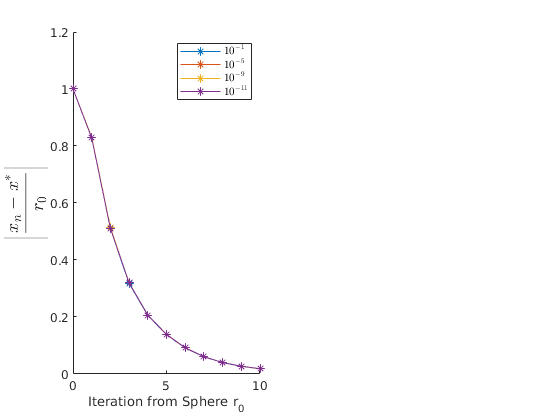

RadRange = [1 5 9 11];

addpath(SaveFolder)
%figure('Name','Diff test')
p = 0.33;
hFig9 = figure('Name','GlobalConv');
subplot 121
hold on
for RadInd = RadRange
    load([SaveFolder sprintf(SaveFName,RadInd,p)],'L2Diff_OneStepAll')
    plot(0:EpocTest-1,median(L2Diff_OneStepAll,1)/10^(-RadInd),'-*',...
        'DisplayName',sprintf('$$10^{-%d}$$',RadInd))
    
end
xlim([0 10])
xlabel('Iteration from Sphere r_0','interpreter','tex');
ylabel('$$\left|\frac{x_n-x^*}{r_0}\right|$$','interpreter','latex','FontSize',14)
legend('Interpreter','latex')

Fig distances for each epoch

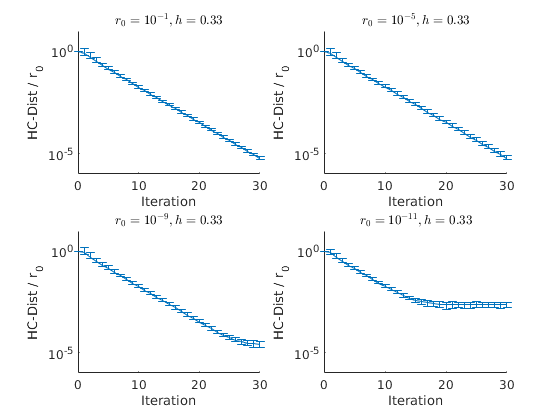

figure('Name','Diff test2')
%RadInd = RadRange;
spIND = 1;
pALL = 0.33;
for RadInd = RadRange
    load([SaveFolder sprintf(SaveFName,RadInd,p)],'L2Diff_OneStepAll','DiffVecAll')
    subplot(2,ceil(length(RadRange)/2),spIND)
    hold on
    DiffAll = L2Diff_OneStepAll/10^(-RadInd);
    med = median(DiffAll,1,'omitnan');
    maxdiff = nanmax(DiffAll,[],1);
    mindiff = nanmin(DiffAll,[],1);
    errorbar(0:size(DiffAll,2)-1,med,med-mindiff,maxdiff-med)
%     for TestInd = 1:size(DiffAll,1)
%         plot(0:size(DiffAll,2)-1,DiffAll(TestInd,:),'Color',[0.7 0.7 0.7],'LineStyle',"-",'LineWidth',0.2)
%     end
%     FIDIff_OnePix = squeeze(DiffVecAll(:,:,201));
%     for SamInd = 1:NSample
%         %plot(DiffAll(SamInd,:))
%         plot(FIDIff_OnePix(SamInd,:)/FIDIff_OnePix(SamInd,end))
%     end
    xlabel('Iteration','interpreter','tex');
    ylabel('HC-Dist / r_0','interpreter','tex')
    title(sprintf('$$r_0 = 10^{-%d}, h=%.2f$$',RadInd,p),'interpreter','latex')
    ylim([10^-6 10^1])
    set(gca,'Yscale','log')
    %xlim([10 21])
    spIND = spIND+1;
end

different Ps

figure('Name','Diff test2')
%RadInd = RadRange;
spIND = 1;
RadInd = 1

RadInd = 1

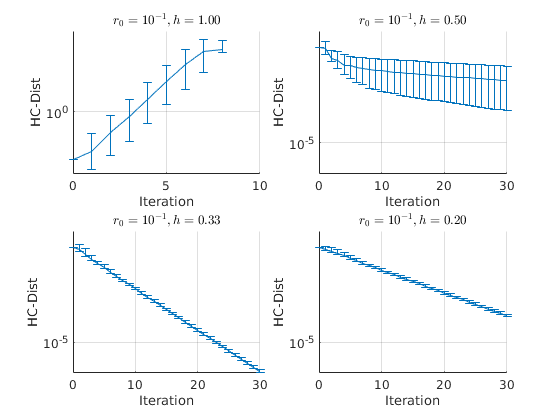

pALL = [1 0.5 0.33 0.2];
ylimAll = [.05 50; repmat([5*10^-7, .5],3,1) ];
for p = pALL
    load([SaveFolder sprintf(SaveFName,RadInd,p)],'L2Diff_OneStepAll','DiffVecAll')
    subplot(2,ceil(length(pALL)/2),spIND)
    hold on
    DiffAll = L2Diff_OneStepAll;%/10^(-RadInd);
    med = median(DiffAll,1,'omitnan');
    maxdiff = nanmax(DiffAll,[],1);
    mindiff = nanmin(DiffAll,[],1);
%     for TestInd = 1:size(DiffAll,1)
%         plot(0:size(DiffAll,2)-1,DiffAll(TestInd,:),'Color',[0.7 0.7 0.7],'LineStyle',"-",'LineWidth',0.2)
%     end
    %FIDIff_OnePix = squeeze(DiffVecAll(:,:,201));
%     for SamInd = 1:NSample
%         %plot(DiffAll(SamInd,:))
%         plot(FIDIff_OnePix(SamInd,:)/FIDIff_OnePix(SamInd,end))
%     end
    errorbar(0:size(DiffAll,2)-1,med,med-mindiff,maxdiff-med)
    xlabel('Iteration','interpreter','tex');
    ylabel('HC-Dist',...
        'interpreter','tex')
    title(sprintf('$$r_0 = 10^{-%d}, h=%.2f$$',RadInd,p),...
        'interpreter','latex','FontSize',13)
    ylim(ylimAll(spIND,:))
    set(gca,'Yscale','log')
    %xlim([10 21])
    spIND = spIND+1;
    grid on
    set(gca, 'YMinorGrid', 'off')
end

Show first few iterations

hFig = figure('Name','Diff iters','Units','normalized','Position',[0 0 0.5 0.30]);
EpocShow = 7;
Panel1 = 2; Panel2 = EpocShow;%length(EpocList);
ha = tight_subplot(Panel1,Panel2,[.04 .02],[.04 .04],[.04 .04]);

load([SaveFolder sprintf(SaveFName,1,1)],'DiffVecAll')
SamInd = 1;
DiffVec1Sample = squeeze(DiffVecAll(SamInd,:,:));
LDEequvE = LDEequv.S*(1-CplxR) + LDEequv.C*CplxR;

for Epoc = 1:EpocShow
    EDiff = DiffVec1Sample(Epoc,1:NPixX*NPixY) * (1-CplxR) + ...
        DiffVec1Sample(Epoc,NPixX*NPixY+1:2*NPixX*NPixY) * CplxR;
    IDiff = DiffVec1Sample(Epoc,2*NPixX*NPixY+1:3*NPixX*NPixY);
    EDiffFld = symmHCs(zeros(N_HCOut^2*NPixX*NPixY,1),N_HCOut,NPixX,NPixY,EDiff','add');   
    IDiffFld = symmHCs(zeros(N_HCOut^2*NPixX*NPixY,1),N_HCOut,NPixX,NPixY,IDiff','add'); 
    axes(ha(Epoc))
    ShowField(EDiffFld,1:1600,40,40)
    title(sprintf('$$f^E(%d)-f^{E*}$$',Epoc-1),'Interpreter',"latex")
    set(gca,'fontsize',15)
    set(gca,'YTickLabel',[]);
    set(gca,'XTickLabel',[]);
    
    axes(ha(Epoc + EpocShow))
    ShowField(IDiffFld,1:1600,40,40)
    title(sprintf('$$f^I(%d)-f^{I*}$$',Epoc-1),'Interpreter',"latex")
    set(gca,'fontsize',15)
    set(gca,'YTickLabel',[]);
    set(gca,'XTickLabel',[]);
    
%     subplot(2,EpocShow,Epoc + 18)
%     ShowField(EDiffFld+LDEequvE,1:1600,40,40,sprintf('fE, iter #%d',Epoc-1))
%     subplot(2,EpocShow,Epoc + 27)
%     ShowField(IDiffFld+LDEequv.I,1:1600,40,40,sprintf('fI, iter #%d',Epoc-1))
end

%FigurDemoPath = [CurrentFolder '/Figures/Demo060322/']; % 
FigName1 = sprintf('Fig6Local_SI_h-%.1f-Sample%d',p,SamInd)

savefig(hFig,[FigurePaperPath FigName1 '.fig']);
exportgraphics(hFig,[FigurePaperPath FigName1 '.pdf'],'Resolution',300)


## 4.3 Global convergence

L2DiffAll_global = [];
addpath([CurrentFolder '/Data/Paper2_NetworkTuning/Fig1V4/GlobConv/'])
p = 0.33;
for Id1 = 1:13
    for Id2 = 1:3
        L2Diff = load(sprintf('Paper2GlobConv_IC%d_Ctrst%d_p%.2f_NewSmear.mat',Id1,Id2,p),'L2Diff_EIWgtsAll');
        L2Diff = L2Diff.L2Diff_EIWgtsAll;
        L2DiffAll_global = [L2DiffAll_global;L2Diff];
    end
end

for Id3 = 1:3
    L2Diff = load(sprintf('Paper2GlobConv_BlockID%d_p%.2f_NewSmear.mat',Id3,p),'L2Diff_EIWgtsAll');
    L2Diff = L2Diff.L2Diff_EIWgtsAll;
    L2DiffAll_global = [L2DiffAll_global;L2Diff];
end


percentiles

SphereNum = 10;
EpocSphere = cell(SphereNum,1);
for RadInd = 1:10
    EpocSphere{RadInd} = zeros(size(L2DiffAll_global,1),1);
end

hFig9 = figure('Name','GlobalConv');
for TestId = 1:size(L2DiffAll_global,1)
    for RadInd = 1:10
        convCurve = L2DiffAll_global(TestId,:);
        EpocSphere{RadInd}(TestId) = length(find(convCurve>10^(-RadInd+2)));
    end
end

P99 = find(EpocSphere{10} == prctile(EpocSphere{10},75));
P01 = find(EpocSphere{10} == prctile(EpocSphere{10},25));

for TestId = 1:size(L2DiffAll_global,1)
    convCurve = L2DiffAll_global(TestId,:);
    
    hold on
    if TestId == P99(end)
        convCurveHigh = convCurve;
    elseif TestId == P01(end)
        convCurveLow = convCurve;
    else
        plot(0:length(convCurve)-1, convCurve,'Color',[0.8,0.8,0.8])
    end
    
    
end
% plot(convCurveHigh,'r','LineWidth',2)
% plot(convCurveLow,'b','LineWidth',2)

Fig parameters

%subplot(3,2,[1,3,5])
set(gca,'YScale','log','FontSize',13)
xlim([0 85]); ylim([1e-10 1e5])

% for RadInd = 8
%     plot([1 201],10^(-RadInd)*ones(1,2),'r--')
% end
xlabel('Iterations','FontSize',18); 
ylabel('HC-Dist','FontSize',18)
grid on; box on
set(gca,'Yminorgrid','off')

inset

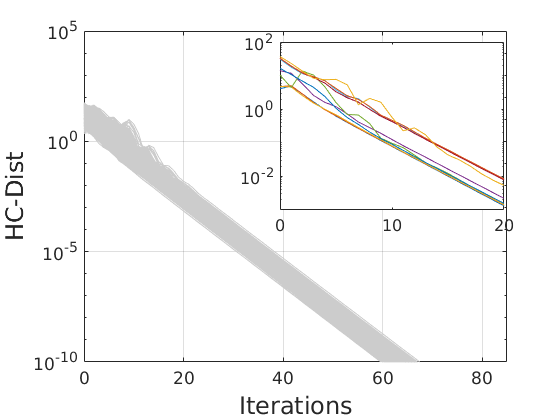

axes('Position',[.5 .5 .4 .4])
hold on
box on
TestUseAll = [randi([1 1500],5,1); 
              randi([1501 size(L2DiffAll_global,1)],5,1)];
for TestId = 1:length(TestUseAll)
    convCurve = L2DiffAll_global(TestUseAll(TestId),:);
    plot(0:length(convCurve)-1, convCurve)
end
axis([0 20 1e-3 1e2]);
set(gca,'YScale','log','FontSize',12)

%plot(x2,y2)

% subplot 122
% 
% %options.handle     = figure(1);
% options.x_axis = 1:10;
% options.color_area = [128 193 219]./255;    % Blue theme
% options.color_line = [ 52 148 186]./255;
% %options.color_area = [243 169 114]./255;    % Orange theme
% %options.color_line = [236 112  22]./255;
% options.alpha      = 0.5;
% options.line_width = 0.5;
% options.error      = 'std4';
% 
% hold on
% data = (cell2mat(EpocSphere'))';
% plot_areaerrorbar((cell2mat(EpocSphere')),options)
% % for RadInd = 1:10
% %     scatter((RadInd-1)*ones(size(L2DiffAll_global,1),1)+0.5*(rand(size(EpocSphere{RadInd}))-1/2),...
% %         EpocSphere{RadInd}+rand(size(EpocSphere{RadInd}))-1/2,0.1,'k.')
% % end
% xticklbl = cell(size(EpocSphere));
% for RadInd = 1:10
%     xticklbl{RadInd} = sprintf('$$10^{%d}$$',-RadInd+2);
% end
% set(gca,'xtick',1:10,'xticklabel',xticklbl,...
%     'TickLabelInterpreter','latex')
% ylabel('Iteration # Reaching the sphere')
% xlabel('Sphere radius')
% xlim([1 10])
% subplot(3,2,2)
% histogram(Epoc1e_0)

% xlim([15 120])
% subplot(3,2,4)
% histogram(Epoc1e_3)
% xlim([15 120])
% xlabel('Iteration # Reaching 10^{-3} Sphere')
% subplot(3,2,6)
% histogram(Epoc1e_9)
% xlabel('Iteration # Reaching 10^{-9} Sphere')
% xlim([15 120])

Save figures

FigName1 = sprintf('Figure8Draft');
savefig(hFig9,[FigurePaperPath FigName1 '.fig']);


Print Figs

hFig9.PaperUnits = 'centimeters';
hFig9.PaperSize = [50,40];
hFig9.PaperOrientation = "landscape";
exportgraphics(hFig9,[FigurePaperPath FigName1 '.pdf'],'Resolution',300)